# Tutorial: Level-k Game Theory for Intersection Navigation

#### Provided by Kyoungtae Ji, Kyoungseok Han*, Hanyang University, Department of Automotive Engineering, 2025. 

#### Contact us: wlrudxo644@hanyang.ac.kr, kyoungsh@hanyang.ac.kr

  In this tutorial, we will develop an autonomous vehicle controller to navigate two vehicles safely through an unsignalized intersection from their initial positions to target destinations  while avoiding collisions. We assume that **other vehicles' intentions are unknown and employ level-k game theory to predict their behavior based on strategic reasoning**. As human drivers exhibit different levels of strategic thinking, we will use **behavior cloning to train neural networks that can instantly replicate the game-theoretic decisions** for real-time implementation.

## Two-Vehicle Intersection System

The system is shown below. There are two cars at an unsignalized intersection:

- Blue car (Car 1, human-driven): Starts from south, going straight north

- Red car (Car 2, ego vehicle): Starts from north, turning east

Both cars enter the intersection simultaneously, creating a potential conflict that requires strategic reasoning.

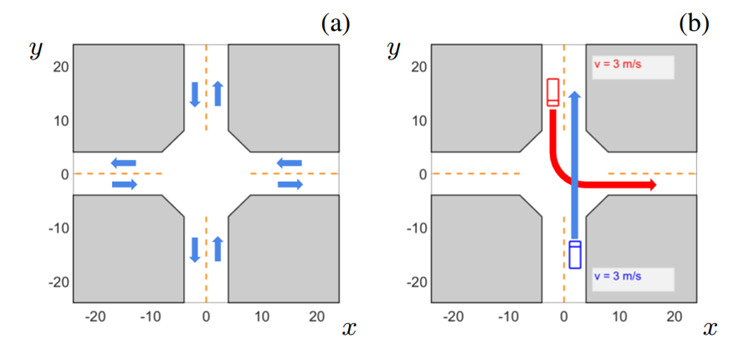

## System Dynamics

### State vector for each vehicle

 
$$X=\left\lbrack x,y,\theta \;,v\right\rbrack$$


- $\left(x,y\right)$ - Position coordinates [m]

- $\theta \;$ - Heading angle [rad]

- $v$ - Velocity [m/s]

### Action space (discrete)


$$A\in \;\left\lbrace 1,2,3,4,5,6\right\rbrace$$


- Maintain current speed and direction: $\left(a,\omega \right)=\left(0,0\right)$

- Turn left: $\left(a,\omega \right)=\left(0,\frac{\pi }{4}\right)$

- Turn right: $\left(a,\omega \right)=\left(0,-\frac{\pi }{4}\right)$

- Accelerate: $\left(a,\omega \right)=\left(2\ldotp 5,0\right)$

- Decelerate: $\left(a,\omega \right)=\left(-2\ldotp 5,0\right)$

- Hard brake: $\left(a,\omega \right)=\left(-5,0\right)$

### Discrete-time System Model

   
$$\begin{array}{l}
x\left(t+1\right)=x\left(t\right)+v\left(t\right)\;\cos \left(\theta \left(t\right)\right)\Delta \;t,\\
\begin{array}{l}
y\left(t+1\right)=y\left(t\right)+v\left(t\right)\;\sin \left(\theta \left(t\right)\right)\Delta \;t,\\
\begin{array}{l}
v\left(t+1\right)=v\left(t\right)+a\left(t\right)\Delta \;t,\\
\theta \left(t+1\right)=\theta \left(t\right)+\omega \;\Delta \;t\ldotp 
\end{array}
\end{array}
\end{array}$$


### Constraints

- $v\in \left\lbrack 0,5\right\rbrack \;$m/s

- Road boundaries must be respected

- Collision avoidance is enforced through reward function

## Level-k framework Demonstration

 In this section, we run a single episode to visualize how vehicles interact using level-k reasoning.

#### Blue vehicle (Car 1): Human-driven, uses Level-1 strategy (human_level)

- Starts from south (-2, -24), heading north

- Assumes the red vehicle is Level-0 (non-strategic)

#### Red vehicle (Car 2): Autonomous ego vehicle, uses adaptive strategy (one level higher than blue car)

- Starts from west (-24, -2), heading east

-  Estimates blue vehicle's level and responds accordingly

 The simulation demonstrates how the red vehicle adapts its strategy based on observations of the blue vehicle's behavior, showcasing the online level estimation and strategic decision-making capabilities of the level-k framework.

clear all; close all; clc;
% Run single episode without internal plotting
human_level = 0;
num_episodes = 1;
is_random = 0;
[X_demo, R_demo, Level_demo, Action_demo, time_demo] = runLevelKSimulation(num_episodes, human_level, is_random);


 Episode = 1
 Steps completed: 5/50
 Steps completed: 10/50
 Steps completed: 15/50
 Steps completed: 20/50
 Steps completed: 25/50
 Steps completed: 30/50
 Steps completed: 35/50
Both vehicles reached destinations!


fprintf('   Average computation time: %.3f ms per step\n', time_demo);

   Average computation time: 266.516 ms per step


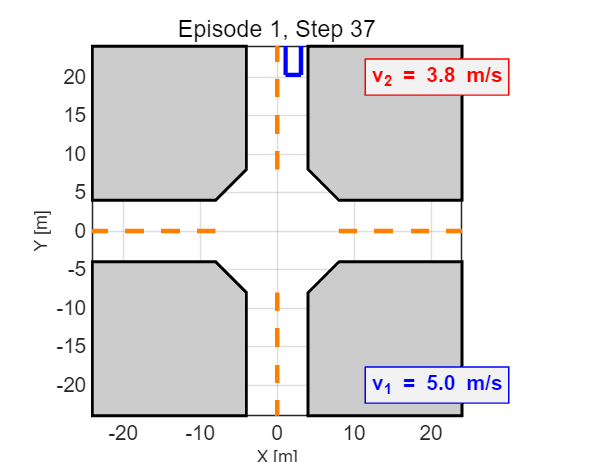

% Display animation using plotSimulationLive
plotSimulationLive(X_demo, 1);

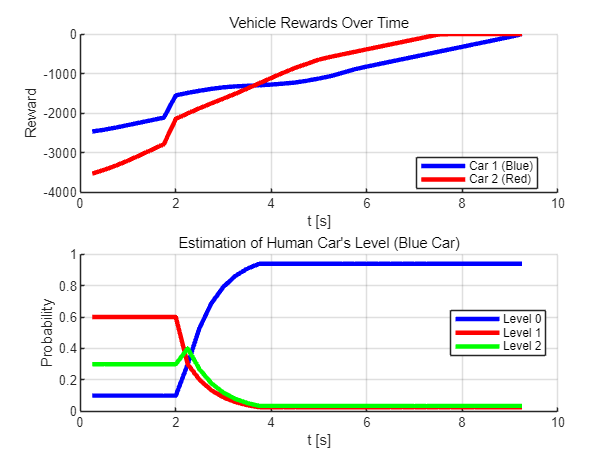

% Display results in a new area
plotSimulationResults(R_demo, Level_demo, 0.25);  % t_step_Sim = 0.25

# Behavior Cloning

Behavior cloning is a form of imitation learning where we **train a neural network to mimic an expert's decisions**. In our case, the "expert" is the level-k game-theoretic controller.

Given a dataset $$\mathcal{D} = \{(s_i, a_i^*)\}_{i=1}^N$$ collected from the expert:: $$s_i = [x_1, y_1, \theta_1, v_1, x_2, y_2, \theta_2, v_2] \in \mathbb{R}^8$$, $ $a_i^* \in \{1, 2, 3, 4, 5, 6\}$$.

We learn a policy $$\pi_\theta: \mathcal{S} \rightarrow A$ $ by minimizing:$$$\mathcal{L}_{BC}(\theta) = -\frac{1}{N} \sum_{i=1}^{N} \log \pi_\theta(a_i^*|s_i)$$$.

This is equivalent to supervised learning with cross-entropy loss for classification. Based on this, we can replace the complex.

#### Note:Since level-k framework compute the 0-3 level optimal action for two agents, we train 8 seperate network for single policy. Meaning that each network is a specific strategy and enables real-time level switching based on opponent estimation.

## Data Collection from Multiple Episodes

In this section, we **collect training data for behavior cloning** by running multiple simulations with the game-theoretic controller. The data collection process ensures diversity and comprehensive coverage of possible scenarios.

We run simulations with varying conditions. Randomize initial positions to explore diverse scenarios, and human level variation (0,1,2) for comprehensive behavioral coverage. 

For each time step, we record:

state: $$[x_1, y_1, \theta_1, v_1, x_2, y_2, \theta_2, v_2]$$

Actions: First actions from all 8 policies (V1-L0, V2-L0, ..., V1-L3, V2-L3)

The resulting **Action_history** has dimensions: [state(1×8), all_level_actions(1×8)] = 16 columns total.

#### Note: for the tutorial, we provide the pre-collected dataset. The save() is commented out in given code.

% Collect data with different human levels for diversity
num_episodes = 100; %For simple test. num_episodes 100 is used in given data.
is_random = 1;
use_nn = 0;
Action_history_all = [];

% Excute the random scenarios with three human levels
for human_level = 0:2
    fprintf('Collecting data with human level %d...\n', human_level);
    [X_history, R_history, Level_ratio_history, Action_history] = ...
        runLevelKSimulation(ceil(num_episodes/3), human_level, is_random, use_nn, []);
    Action_history_all = [Action_history_all; Action_history];
end


 Episode = 1
 Steps completed: 5/50
 Steps completed: 10/50
 Steps completed: 15/50
 Steps completed: 20/50
 Steps completed: 25/50
 Steps completed: 30/50
 Steps completed: 35/50
Both vehicles reached destinations!

 Episode = 2
 Steps completed: 5/50
 Steps completed: 10/50


Action_history = Action_history_all;

fprintf('Total data points collected: %d\n', size(Action_history, 1));
% Save collected data
% save('Action_history.mat', 'Action_history');  % Comment out if using pre-collected data

## Train Neural Networks

  In this section, we implement **behavior cloning by training neural networks to imitate the level-k game-theoretic controller**. Each network learns to map states directly to actions, bypassing the computationally expensive tree search. 

We train 8 separate neural networks, one for each vehicle-level pair (2 vehicles × 4 levels). The the dummyvar() function converts discrete action $a\in \left\lbrace 1,2,3,4,5,6\right\rbrace$ into one-hot vector for training such as $\left\lbrack 0,1,0,0,0,0\right\rbrack$.

Each network uses:

- 8 input neurons (joint state of both vehicles)

- [64, 32, 16] hidden layer neurons

- 6 output neurons (action probabilities)

  The training uses 70/15/15 train/validation/test split with cross-entropy loss and scaled conjugate gradient optimization. After training, we visualize the confusion matrix and training  performance to verify successful imitation learning.

#### Note: for the tutorial, we provide the pre-learned NN models. The save() is commented out in given code.

% Load pre-collected training data
load('Action_history.mat');  % Load saved Action_history of num_episodes = 100
fprintf('Total data points: %d\n', size(Action_history, 1));

Total data points: 3691


Training NN_V1_0... 

Train: 86.8%, Val: 83.6%, Test: 83.2%


Training NN_V2_0... 

Train: 87.7%, Val: 85.7%, Test: 85.4%


Training NN_V1_1... 

Train: 89.4%, Val: 89.5%, Test: 89.4%


Training NN_V2_1... 

Train: 81.2%, Val: 83.2%, Test: 80.5%


Training NN_V1_2... 

Train: 91.2%, Val: 88.6%, Test: 89.9%


Training NN_V2_2... 

Train: 90.4%, Val: 89.7%, Test: 87.4%


Training NN_V1_3... 

Train: 90.2%, Val: 89.5%, Test: 90.3%


Training NN_V2_3... 

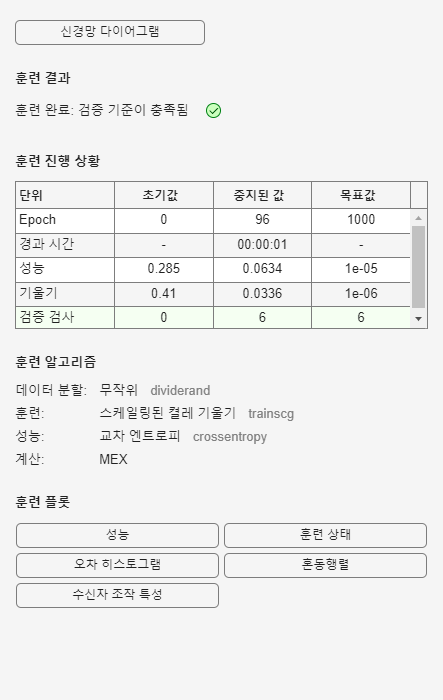

Train: 83.9%, Val: 82.1%, Test: 83.4%


% Prepare data for NN training
% Action_history format: [state (8 values), all_actions (8 values)]
X_train = Action_history(:, 1:8)';  % 8xN matrix for NN input

% Train 8 neural networks (one for each vehicle-level combination)
% Network architecture
hiddenLayerSize = [64, 32, 16];  % Larger network for overfitting
trainFcn = 'trainscg';  % Scaled conjugate gradient

% Initialize NN models struct
NN_models = struct();

% Define network names and corresponding data columns
network_info = {
    'NN_V1_0', 9;   % Vehicle 1, Level 0
    'NN_V2_0', 10;  % Vehicle 2, Level 0
    'NN_V1_1', 11;  % Vehicle 1, Level 1
    'NN_V2_1', 12;  % Vehicle 2, Level 1
    'NN_V1_2', 13;  % Vehicle 1, Level 2
    'NN_V2_2', 14;  % Vehicle 2, Level 2
    'NN_V1_3', 15;  % Vehicle 1, Level 3
    'NN_V2_3', 16;  % Vehicle 2, Level 3
};

% Train all networks
for i = 1:size(network_info, 1)
    net_name = network_info{i, 1};
    data_col = network_info{i, 2};
    
    fprintf('Training %s... ', net_name);
    
    % Get target actions for this network
    Y_train = Action_history(:, data_col);
    
    % Create and configure network
    net = patternnet(hiddenLayerSize, trainFcn);
    
    % Disable training window for all networks
    net.trainParam.showWindow = 1;
    
    % Use 70/15/15 split for imitation learning
    % This is standard for behavioral cloning to prevent overfitting
    net.divideParam.trainRatio = 0.7;   % 70% for training
    net.divideParam.valRatio = 0.15;    % 15% for validation (early stopping)
    net.divideParam.testRatio = 0.15;   % 15% for testing
    
    % Use 'dividerand' for random sampling (default)
    % This ensures diverse situations in each set
    net.divideFcn = 'dividerand';
    
    % Set training parameters
    net.trainParam.epochs = 1000;       % Maximum epochs
    net.trainParam.goal = 1e-5;         % Performance goal
    
    % Train network
    [net, tr] = train(net, X_train, dummyvar(Y_train)');
    
    % Store in struct
    NN_models.(net_name) = net;
    
    % Calculate and display accuracy for all three sets
    train_indices = tr.trainInd;
    val_indices = tr.valInd;
    test_indices = tr.testInd;
    
    % Training accuracy
    train_accuracy = sum(vec2ind(net(X_train(:, train_indices)))' == Y_train(train_indices)) / length(train_indices) * 100;
    
    % Validation accuracy
    val_accuracy = sum(vec2ind(net(X_train(:, val_indices)))' == Y_train(val_indices)) / length(val_indices) * 100;
    
    % Test accuracy
    test_accuracy = sum(vec2ind(net(X_train(:, test_indices)))' == Y_train(test_indices)) / length(test_indices) * 100;
    
    fprintf('Train: %.1f%%, Val: %.1f%%, Test: %.1f%%\n', train_accuracy, val_accuracy, test_accuracy);
end


% Save trained models
% save('trained_NN_models.mat', 'NN_models'); % Comment out if using pre-collected data
fprintf('\nAll neural networks trained and saved!\n');


All neural networks trained and saved!


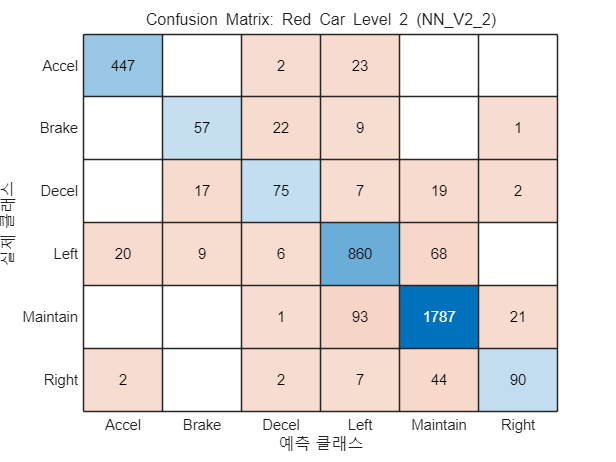

% Visualize confusion matrix for one of the networks
clf;
% Get the correct target data for V2_L2 (column 14 in Action_history)
Y_target_V2_L2 = Action_history(:, 14);  % Red car, Level 2 actions
Y_pred = vec2ind(NN_models.NN_V2_2(X_train));
cm = confusionmat(Y_target_V2_L2, Y_pred');
confusionchart(cm, {'Maintain', 'Left', 'Right', 'Accel', 'Decel', 'Brake'});
title('Confusion Matrix: Red Car Level 2 (NN\_V2\_2)');

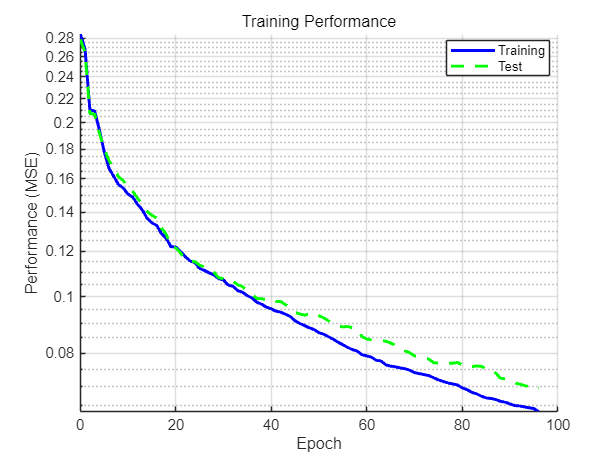

% Plot training history summary
figure; 
hold on;
plot(tr.epoch, tr.perf, 'b-', 'LineWidth', 2);
plot(tr.epoch, tr.tperf, 'g--', 'LineWidth', 2);
xlabel('Epoch');
ylabel('Performance (MSE)');
title('Training Performance');
legend('Training', 'Test', 'Location', 'best');
grid on;
set(gca, 'YScale', 'log');

## Test Neural Network Control

 In this section, we compare the original game-theoretic controller with the trained neural networks to validate our behavior cloning approach. 

The comparison focuses on three key aspects: **computational speed, trajectory similarity, and action consistency**.

The computeLevelKStrategies_NN function replaces the tree search with direct neural network inference. Instead of evaluating 6^4 = 1,296 possible paths, it simply:

-   Formats the current state as an 8D vector

-   Passes it through each trained network

-   Returns the highest probability action (using vec2ind)

This reduces complexity of controller, **enabling real-time execution**.

### Performance Comparison

We run identical scenarios with both controllers:

- Game Theory: Original tree search algorithm (baseline)

- Neural Network: Trained behavior cloning models

The simulation uses the same initial conditions (human_level=2, fixed positions) to ensure fair comparison.

% Load trained NN models
load('trained_NN_models.mat');
num_episodes = 1;
human_level = 1;
is_random = 0;

% Test both game theory and NN approaches
fprintf('1. Running with Game Theory (baseline)...\n');

1. Running with Game Theory (baseline)...


use_nn = 0;
[X_GT, R_GT, Level_GT, Action_GT, time_GT] = runLevelKSimulation(num_episodes, human_level, is_random,use_nn);


 Episode = 1
 Steps completed: 5/50
 Steps completed: 10/50
 Steps completed: 15/50
 Steps completed: 20/50
 Steps completed: 25/50
 Steps completed: 30/50
 Steps completed: 35/50
Both vehicles reached destinations!


fprintf('   Average computation time: %.3f ms per step\n', time_GT);

   Average computation time: 259.931 ms per step


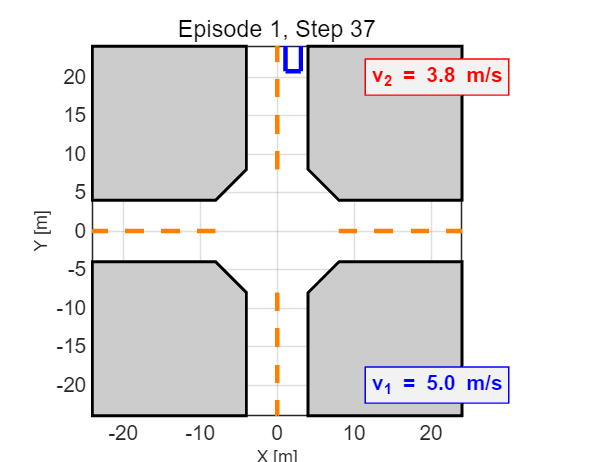

plotSimulationLive(X_GT, 1);


fprintf('\n2. Running with Neural Networks...\n');


2. Running with Neural Networks...


use_nn = 1;
[X_NN, R_NN, Level_NN, Action_NN, time_NN] = runLevelKSimulation(num_episodes, human_level, is_random, use_nn, NN_models);


 Episode = 1
 Steps completed: 5/50
 Steps completed: 10/50
 Steps completed: 15/50
 Steps completed: 20/50
 Steps completed: 25/50
 Steps completed: 30/50
Both vehicles reached destinations!


fprintf('   Average computation time: %.3f ms per step\n', time_NN);

   Average computation time: 37.409 ms per step


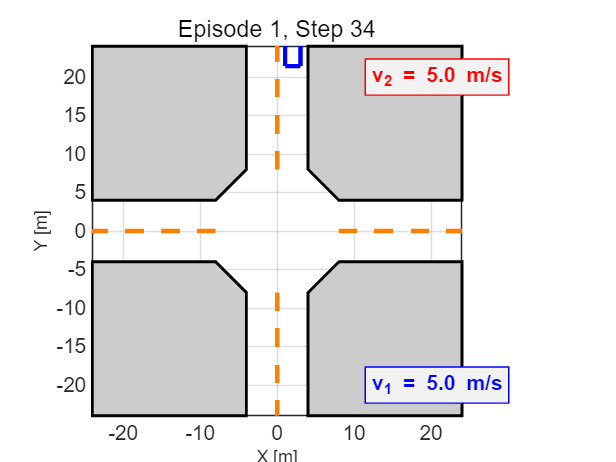

plotSimulationLive(X_NN, 1);

fprintf('\nSpeedup: %.1fx faster\n', time_GT/time_NN);


Speedup: 6.9x faster


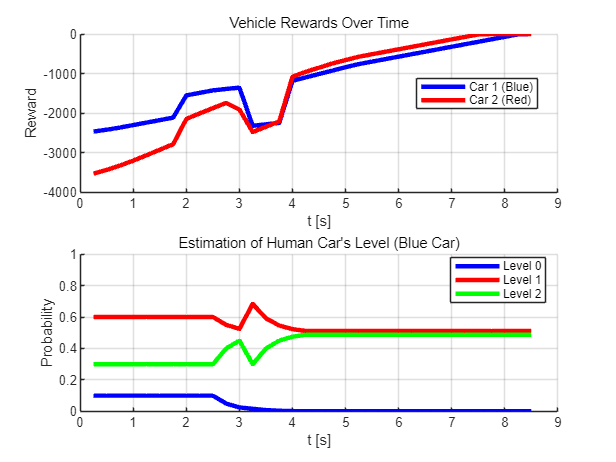

% Display results in a new area
plotSimulationResults(R_NN, Level_NN, 0.25);  % t_step_Sim = 0.25

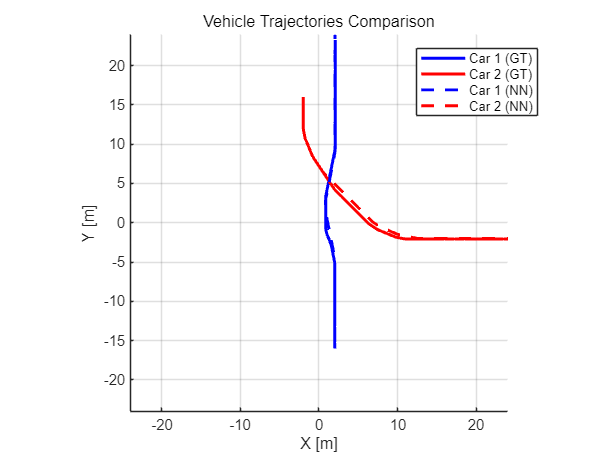

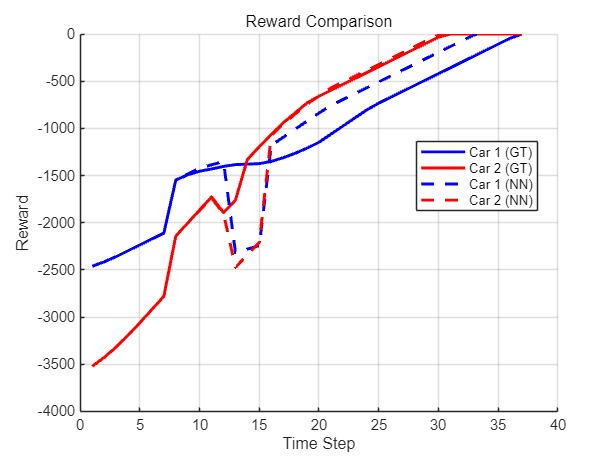

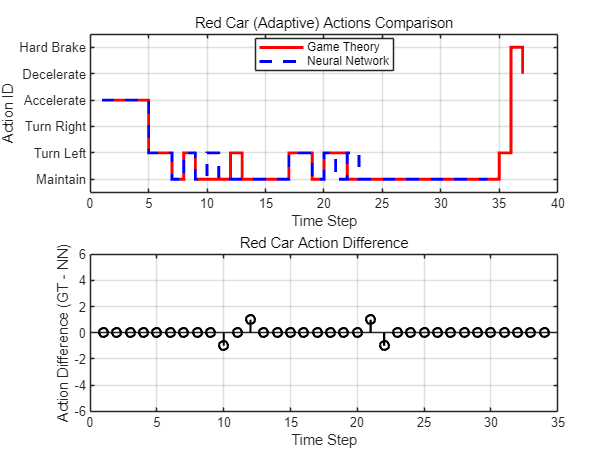

% Compare results using the plotComparison function
plotComparison(X_GT, R_GT, Level_GT, Action_GT, X_NN, R_NN, Level_NN, Action_NN);

# Level-k Framework

 We consider a multi-agent intersection scenario where **each vehicle **$i$** must select a sequence of discrete actions** $$\gamma_i = (\gamma_{i,0}, \gamma_{i,1}, ..., \gamma_{i,N-1})$$ over a finite horizon $N$. The key challenge is that each vehicle's optimal strategy depends on the strategies of other vehicles, creating a coupled decision problem.

For a level-k agent, the optimal action sequence $$\hat{\gamma}^{ego}_k$$ is obtained by  solving:

$$\hat{\gamma}^{ego}_k\in  \underset{\gamma_i \in \Gamma}{\text{argmax}} \mathcal{R}_k(\gamma),$$ where  $$\Gamma$$ denotes the set of feasible action sequences. The objective function $$\mathcal{R}_k(\gamma)$$ represents the expected cumulative reward when the ego vehicle follows strategy $$\gamma$$ while assuming other vehicles are level-(k-1) agents: $\mathcal{R}_k(\gamma) = \sum_{i=0}^{n-1} \gamma^i R_i (\gamma \mid \hat{\gamma}^{other}_{k-1})
$.

The stage reward $R_{i\;}$ at time step $i$ depends on the entire history of actions up to that  point, as well as the predicted future actions of other agents:

$$R_i(\gamma \mid \hat{\gamma}^{other}_{k-1} = R(\gamma_i \mid s_0, \gamma_0, \dots, \gamma_{i-1}, \hat{\gamma}^{others}_{(k-1,0)}, \dots, \hat{\gamma}^{other}_{(k-1,i)})$$.

#### Note: This requires computing strategies for all k+1 levels (0 through k), with each level requiring tree search for both agents.

function [action_ids, Q_values, X_pseudos] = computeLevelKStrategies(X_old, num_cars, action_space, t_step_DT, max_level)
% Compute all level-k strategies from L0 to max_level
% Returns cell arrays containing actions, Q-values, and pseudo states for each level

% Initialize storage for all levels
action_ids = cell(max_level+1, 1);  % L0 to L[max_level]
Q_values = cell(max_level+1, 1);
X_pseudos = cell(max_level+1, 1);

% Each level stores data for all cars
for level = 0:max_level
    action_ids{level+1} = cell(num_cars, 1);
    Q_values{level+1} = cell(num_cars, 1);
end

%% Level-0 computation
for car_id = 1:num_cars
    [Q_values{1}{car_id}, action_ids{1}{car_id}] = DecisionTree_L0(X_old, car_id, action_space, t_step_DT);
end

% Simulate L0 actions
X_temp = X_old;
X_pseudo_L0 = zeros(size(X_old,1), size(X_old,2), length(action_ids{1}{1}));
for step_idx = 1:length(action_ids{1}{1})
    for car_id = 1:num_cars
        X_temp = Motion_Update(X_temp, car_id, action_ids{1}{car_id}(step_idx), t_step_DT);
    end
    X_pseudo_L0(:,:,step_idx) = X_temp;
end
X_pseudos{1} = X_pseudo_L0;

%% Level-k computation (k >= 1)
for level = 1:max_level
    % Prepare X_pseudo_Id for each car based on previous level
    X_pseudo_prev_Id = cell(num_cars, 1);
    for car_id = 1:num_cars
        X_pseudo_prev_Id{car_id} = X_pseudos{level};
        % Reset ego vehicle position to current state
        for pre_step = 1:size(X_pseudos{level}, 3)
            X_pseudo_prev_Id{car_id}(:, car_id, pre_step) = X_old(:, car_id);
        end
    end
    
    % Compute level-k actions for all cars
    for car_id = 1:num_cars
        [Q_values{level+1}{car_id}, action_ids{level+1}{car_id}] = ...
            DecisionTree_L1(X_pseudo_prev_Id{car_id}, car_id, action_space, t_step_DT);
    end
    
    % Simulate level-k actions
    X_temp = X_old;
    X_pseudo_Lk = zeros(size(X_old,1), size(X_old,2), length(action_ids{level+1}{1}));
    for step_idx = 1:length(action_ids{level+1}{1})
        for car_id = 1:num_cars
            X_temp = Motion_Update(X_temp, car_id, action_ids{level+1}{car_id}(step_idx), t_step_DT);
        end
        X_pseudo_Lk(:,:,step_idx) = X_temp;
    end
    X_pseudos{level+1} = X_pseudo_Lk;
end

end

### Decision Tree

To compute optimal action sequence, decision tree is employed. We compute all possible actions in action space for 4-steps, and compare the cumulative reward.

The computational complexity of decision tree is $O\left(A^N \right)$ (In this setting, prediction horizon = 4, action space = 6, agents = 2, so total computation for all levels is $O\left(4\times 6^4 \times 2\right)$

#### Note: The other car's action sequence is assumed to be the optimal sequence for level- k-1 agent.

%% Decision Tree for Level-1 (considers opponent's predicted behavior)
function [Q_value_opt, Action_id] = DecisionTree_L1(X_pseudo, car_id, action_space, t_step_DT)

% Discount factor for future rewards
discount = 0.8;

% Number of actions and lookahead steps
num_actions = length(action_space);
num_steps = 4;

% Initialize arrays to store best Q-value and action sequence
best_Q = -inf;
best_actions = zeros(num_steps, 1);

% Exhaustively search all possible 4-step action sequences
for id_1 = 1:num_actions
    % Step 1: Start with predicted state at time 1
    X1 = X_pseudo(:,:,1);
    % Update only ego vehicle
    X1 = Motion_Update(X1, car_id, action_space(id_1), t_step_DT);
    R1 = Reward(X1, car_id, action_space(id_1));
    
    for id_2 = 1:num_actions
        % Step 2: Use predicted state at time 2, but keep ego's position from step 1
        X2 = X_pseudo(:,:,2);
        X2(:,car_id) = X1(:,car_id);  % Keep ego vehicle's state from previous step
        % Update ego vehicle
        X2 = Motion_Update(X2, car_id, action_space(id_2), t_step_DT);
        R2 = Reward(X2, car_id, action_space(id_2));
        
        for id_3 = 1:num_actions
            % Step 3: Use predicted state at time 3, but keep ego's position from step 2
            X3 = X_pseudo(:,:,3);
            X3(:,car_id) = X2(:,car_id);  % Keep ego vehicle's state from previous step
            % Update ego vehicle
            X3 = Motion_Update(X3, car_id, action_space(id_3), t_step_DT);
            R3 = Reward(X3, car_id, action_space(id_3));
            
            for id_4 = 1:num_actions
                % Step 4: Use predicted state at time 4, but keep ego's position from step 3
                X4 = X_pseudo(:,:,4);
                X4(:,car_id) = X3(:,car_id);  % Keep ego vehicle's state from previous step
                % Update ego vehicle
                X4 = Motion_Update(X4, car_id, action_space(id_4), t_step_DT);
                R4 = Reward(X4, car_id, action_space(id_4));
                
                % Calculate total Q-value with discount factor
                Q_total = R1 + R2*discount + R3*discount^2 + R4*discount^3;
                
                % Update best if this sequence is better
                if Q_total > best_Q
                    best_Q = Q_total;
                    best_actions = [action_space(id_1); action_space(id_2); 
                                   action_space(id_3); action_space(id_4)];
                end
            end
        end
    end
end

% Return results
Q_value_opt = best_Q;
Action_id = best_actions;

end

### Level Estimation

For opponent level estimation, we employ a heusistic belief update method where **each vehicle maintains a probability distribution over possible opponent levels**, which is updated based on observed actions.

function Level_ratio = updateLevelEstimation(Level_ratio, Action_id, L0_action_id, L1_action_id, L2_action_id)
%% Update level estimation based on observed actions
% Inputs:
%   Level_ratio - Current level estimation matrix (num_cars x 3)
%   Action_id - Actual actions taken by each car (cell array)
%   L0_action_id, L1_action_id, L2_action_id - Actions suggested by each level
% Output:
%   Level_ratio - Updated level estimation

num_cars = 2;
for car_id = 1:num_cars
    opponent_id = 3 - car_id;
    
    % Skip if all levels suggest same action
    if L0_action_id{opponent_id}(1) == L1_action_id{opponent_id}(1) && ...
       L1_action_id{opponent_id}(1) == L2_action_id{opponent_id}(1)
        continue;
    end
    
    % Update belief based on observed action
    if Action_id{opponent_id} == L0_action_id{opponent_id}(1)
        Level_ratio(car_id,1) = Level_ratio(car_id,1) + 0.5;
    end
    if Action_id{opponent_id} == L1_action_id{opponent_id}(1)
        Level_ratio(car_id,2) = Level_ratio(car_id,2) + 0.5;
    end
    if Action_id{opponent_id} == L2_action_id{opponent_id}(1)
        Level_ratio(car_id,3) = Level_ratio(car_id,3) + 0.5;
    end
    
    % Normalize
    Level_ratio(car_id,:) = Level_ratio(car_id,:) / sum(Level_ratio(car_id,:));
end
end

### Level-k Framework with Behavior Cloning

**The Behavior cloning is implimented to imitate the level-k game-theoretic controller**. Each network learns to map states directly to actions, bypassing the computationally expensive tree search. 

function [action_ids, Q_values] = computeLevelKStrategies_NN(X_old, num_cars, NN_models)

% Initialize storage (4 levels: L0, L1, L2, L3)
action_ids = cell(4, 1);
Q_values = cell(4, 1);  % Empty for NN version

% Each level stores actions for all cars
for level = 1:4
    action_ids{level} = cell(num_cars, 1);
    Q_values{level} = cell(num_cars, 1);
end

% Prepare state vector for NN (8D: [x1,y1,θ1,v1,x2,y2,θ2,v2])
State = [X_old(1:4,1); X_old(1:4,2)];

% Get actions from neural networks for current state only
% Level-0
action_ids{1}{1} = vec2ind(NN_models.NN_V1_0(State));
action_ids{1}{2} = vec2ind(NN_models.NN_V2_0(State));

% Level-1
action_ids{2}{1} = vec2ind(NN_models.NN_V1_1(State));
action_ids{2}{2} = vec2ind(NN_models.NN_V2_1(State));

% Level-2
action_ids{3}{1} = vec2ind(NN_models.NN_V1_2(State));
action_ids{3}{2} = vec2ind(NN_models.NN_V2_2(State));

% Level-3
action_ids{4}{1} = vec2ind(NN_models.NN_V1_3(State));
action_ids{4}{2} = vec2ind(NN_models.NN_V2_3(State));

end